# Estimating the Observed Radiance at locations away from solar disk during Sunset using Single Scattering

By Andrew John Buggee

## Define constants 

clear variables

% introduce constants
con = physical_constants;

% depth of the atmopshere at zenith
H = 100;                                % km - atmospheric depth

% Earth's radius
Re = con.R_earth/1e3;                   % km - Earths radius

% average distance between the Earth and Sun
AU = con.au/1e3;                        % km - average distance between Earth and Sun

% Lets define the solar zenith angle
theta0 = 90;                             % deg - solar zenith angle

% Lets pick an observer zenith angle

theta = [45:10:85,86:89];                             % deg - obvserver zenith angle

% find the number of theta angles
N_T = length(theta);

% Define the Opactity file to use
%opc_file = 'psg_opc_1percent_H2O.txt';
opc_file = 'psg_opc_3percent_H2O.txt';

## Lets find the line of sight and the solar distance


% Compute the line of sight path through the atmosphere for the given
% observer zenith angle

% This equation is a quardratic. We will select the positive values

L = [-Re*cosd(theta) + sqrt(Re^2 * cosd(theta).^2 + (H^2 + 2*Re*H));...
    -Re*cosd(theta) - sqrt(Re^2 * cosd(theta).^2 + (H^2 + 2*Re*H))];

index_positive = L>=0;                   % find the L values greater than 0
L = L(index_positive)';
% let sample 10 points along this line of sight
N_L = 10;

% Start at some small distance from the observer
L_start = 1;                                         % km
% We also don't want to have our final point be at the top of the
% atmosphere because then there is not travel path, S_p, through the
% atmopshere

% define a distance off of from the end of L
L_end = 1;                                      % km

L_p = zeros(N_T,N_L);

for tt = 1:N_T
    L_p(tt,:) = linspace(L_start,L(tt) - L_end,N_L);             % km - sampled points along our line of sight, L
end


% Compute the line of sight path through the atmosphere for the given
% solar zenith angle

% This equation is a quardratic. We will select the positive values

% L0 = [-Re*cosd(theta0) + sqrt(Re^2 * cosd(theta0).^2 + (H^2 + 2*Re*H));...
%     -Re*cosd(theta0) - sqrt(Re^2 * cosd(theta0).^2 + (H^2 + 2*Re*H))];
% 
% index_positive = L0>=0;                   % find the L values greater than 0

L0 = -Re*cosd(theta0) + sqrt(Re^2 * cosd(theta0).^2 + (H^2 + 2*Re*H));

% Using this, lets find the distance between the observer and the sun

d = L0 + AU;            % km - distance between the observer and the sun



## Lets find the points along the line of sight that visible to the sun

% ----- ASSUMPTION -----
% We assume the sun is a point source for the geometry calcs

% When the sun is above the horizon, all points along the observers line of
% sight are visible.

% When the sun is below horizon, only certain points along the line of
% sight are visible to the sun. The Earth blocks some of this light.

% ----- ASSUMPTION -----
% For now I'm not computing the points along our line of sight that are
% blocked by the Earth. I'm hoping that these rays will be negligible since
% the have to travel through a lot of dense atmosphere. Later on I can
% figure out the geometry of this problem


## Compute the solar path length through the atmosphere for each point along our line of sight

% First we compute the distance, s, between the sun and the point along our
% line of sight

S = sqrt(d.^2 + L_p.^2 - 2*d*L_p.*cosd(theta0 - repmat(theta',1,N_L)));     % km


% Next we compute the scattering angle
theta_scat = acosd(-(d.^2 - S.^2 - L_p.^2)./(2*S.*L_p));        % deg

% Compute a couple of angles that make the calculations easier
% Refer to the diagram

B = theta_scat - repmat(theta',1,N_L);                                     % deg

A = 180 - B;                                                 % deg

C = 180 - theta_scat;                                        % deg

D = 180 - repmat(theta',1,N_L);                              % deg

% Compute H_p

% ---- ISSUE -----
% Some H_p's are longer than the height of the atmopshere because they exit
% the atmopshere before cross over the zenith line. Not sure what to do
% about this
H_p = L_p .* (sind(C)./sind(B));                              % km

% Lets compute Z_p, the height above the surface of the Earth where our
% point lies. This tells us the temperature and pressure of the location

Z_p = sqrt(Re^2 + L_p.^2 - 2*Re*L_p.*cosd(D)) - Re;                 % km above the Earth's surface

% Compute S_pp

S_pp = L_p .* (sind(repmat(theta',1,N_L))./sind(B));                         % km

% We can now compute S_ppp
% This is a quadratic and we should only take the positive value

% S_ppp = [(Re + H_p).*cosd(A) + sqrt((Re+H_p).^2 .* cosd(A).^2 + (H^2 - H_p.^2 + 2*Re*(H - H_p)));...
%     (Re + H_p).*cosd(A) - sqrt((Re+H_p).^2 .* cosd(A).^2 + (H^2 - H_p.^2 + 2*Re*(H - H_p)))];         % km
% 
% index_positive = S_ppp>=0;
% S_ppp = reshape(S_ppp(index_positive),N_T,[]);


S_ppp = (Re + H_p).*cosd(A) + sqrt((Re+H_p).^2 .* cosd(A).^2 + (H^2 - H_p.^2 + 2*Re*(H - H_p)));         % km

% Some values of S_ppp are negative when the sun is below the horizon. We
% can ignore these values, I think. Lets set them to zero for now
S_ppp(S_ppp<0) = 0;


% Now we can compute the path length a solar ray travels through our
% atmopshere before striking the point L_p

S_p = (2*Re + H + Z_p).*(H - Z_p)./(S_pp + S_ppp);                       % km

## Lets make a plot of the Geometry of our problem

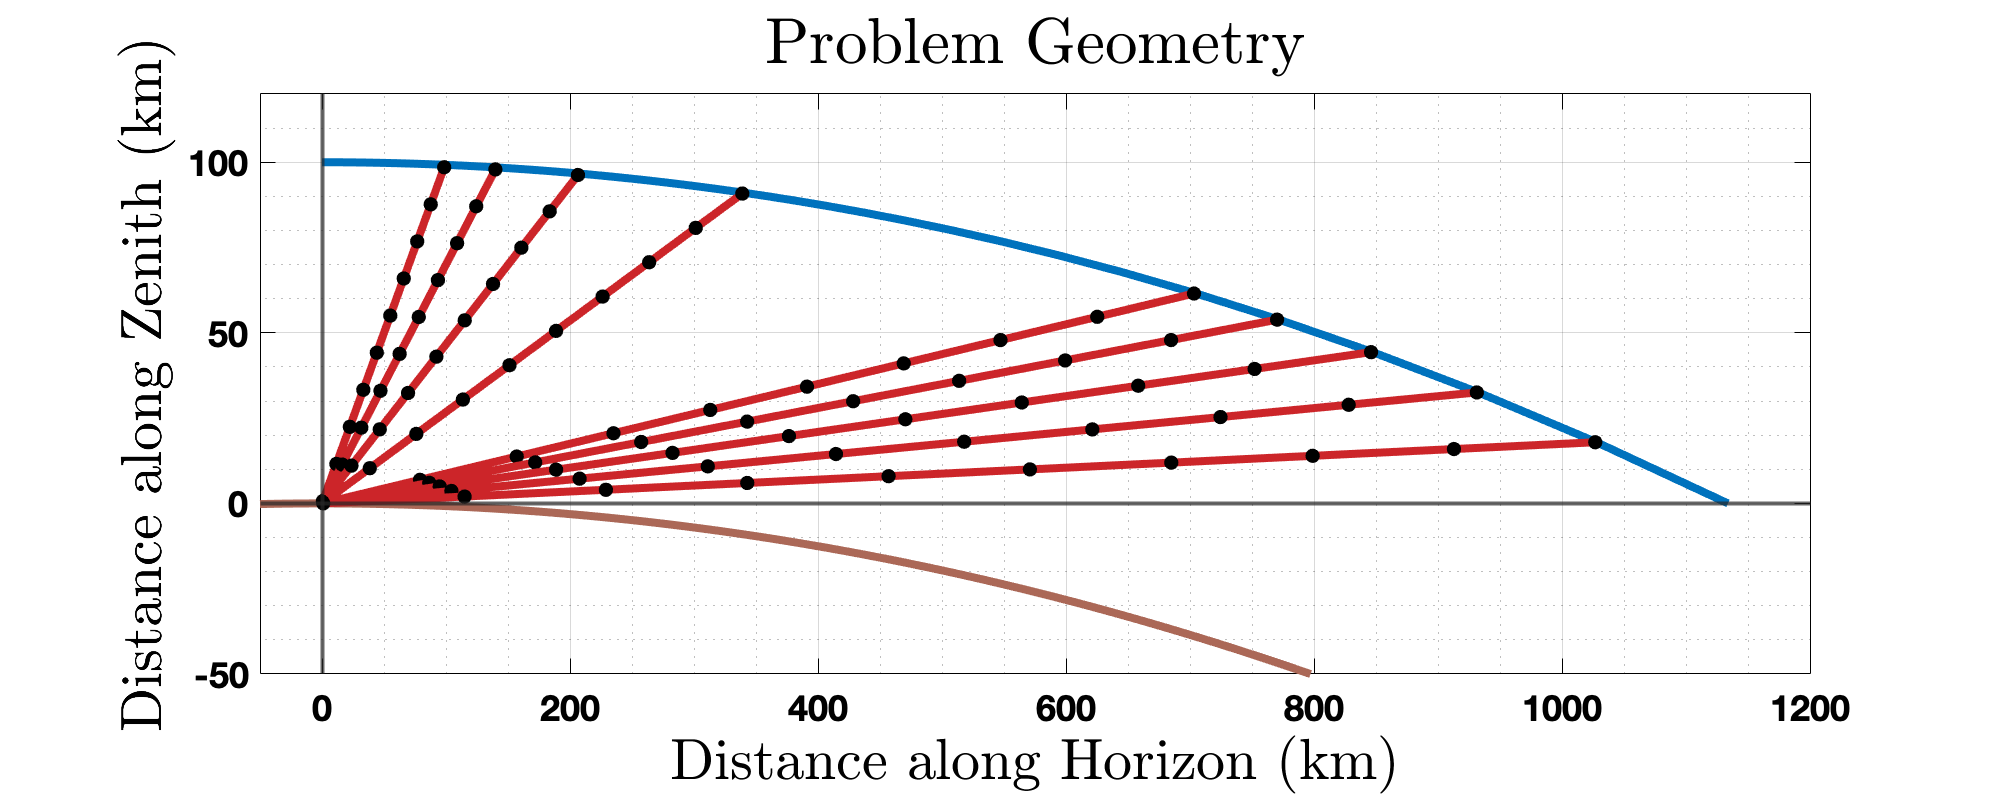

% Lets plot the dome of the sky from some observers perspective
% Compute the line of sight path through the atmosphere for the given
% observer zenith angle

% This equation is a quardratic. We will select the positive values
t = 0:90;

Lt = -Re*cosd(t) + sqrt(Re^2 * cosd(t).^2 + (H^2 + 2*Re*H));

% Great Circle of the Atmosphere
x_atm = Lt.*sind(t);
y_atm = Lt.*cosd(t);

% Great Circle of the Earth
x_earth = -50:800;
% Shift the center of this circle to be at (0,-Re)
y_earth = sqrt(Re^2 - x_earth.^2) - Re;

brwn = [171, 104, 87]./255;             % Color Brown

% Let's plot the atmosphere circle

f = figure; plot(x_atm,y_atm)
hold on
% Lets plot the Earths circle
plot(x_earth,y_earth,'Color',brwn)
% Lets plot the lines of sight
redColor = [204, 37, 41]./255;
for tt = 1:N_T
    % Plot the line of sight
    plot([0,L(tt).*sind(theta(tt))],[0,L(tt).*cosd(theta(tt))],'Color',redColor,'LineStyle',"-")
    
    % plot the discrete locations along the line of sight that we use to
    % determine the scattering contribution
    plot(L_p(tt,:).*sind(theta(tt)), L_p(tt,:).*cosd(theta(tt)),'k.','MarkerSize',20)
end
grid on; grid minor
xlabel('Distance along Horizon (km)','interpreter','latex')
ylabel('Distance along Zenith (km)', 'interpreter','latex')
title('Problem Geometry','interpreter','latex')
set(f, 'Position', [0 0 1000 400])
ylim([-50,120]); xlim([-50,1200])
xline(0,'LineWidth',2); yline(0,'LineWidth',2)

## We need to know the temperature and pressure along S_p

% Along our path S_p, the altitude ranges from Z_p to H
% Lets sample along S_p for the altitude, but lets not sample the upper
% boundary of the atmopshere

N_Z = 10;           % Number of sample points for our optical depth integral

Z_pp = zeros(N_T,N_L,N_Z);

for tt = 1:N_T
    for ll = 1:N_L
        Z_pp(tt,ll,:) = linspace(Z_p(tt,ll),H,N_Z);                       % km - Altitude along S_p
    end
end

% --- Read in 1976 US Standard Atmosphere ---
altitude_boundaries = [0,H];                        % range of altitudes

[altitude, P,T,air_Nc] = read_atm_profile(altitude_boundaries, 'atm_profile_no_cloud.txt');

% ------------------------------------------------------------------
% Interpolate to find the values of temperature and pressure at each
% point in the Z_pp matrix

P_z = interp1(altitude,P,Z_pp,'spline');                    % hPa (mb)
T_z = interp1(altitude, T, Z_pp, 'spline');                 % K
Nc_z = interp1(altitude, air_Nc, Z_pp, 'spline');           % cm^(-3)


## Compute the Transmission along each path length Sp

% we start by defining the wavelength range of interest
% wl_min = 350;                           % nm
% lw_max = 850;                           % nm
% wl = wl_min:wl_max;                     % nm

% ---- READ IN THE EXTINCTION CROSS SECTIONS -----
[wl, sigma_e] = read_psg_opacities(opc_file);      % wl (nm), sigma_e (cm^2/molecule)

% Compute number of wavelengths
N_W = length(wl);

% --- set up the optical depth matrix ---
% We need to compute the optical depth along each S_p line
% lets step through each point L_p
% we need to create an s vector that defines the path
% this vector needs to be the same length as our Z_p vector associate with
% each S_p line

tau = zeros(N_W, N_L, N_T);

% Step through each viewing angle theta
for ww = 1:N_W
    % Step through each point along each line of sight L
    for ll = 1:N_L

        ds = linspace(0,S_p(tt,ll),N_Z);                       % km

        % Step through each wavelength
        for tt = 1:N_T

            % convert units from cm to km
            tau(ww,ll,tt) = trapz(ds,(Nc_z(tt,ll,:).*sigma_e(ww))*1e5);       % unitless
        end
    end
end

% Now we can compute the transmission
T = exp(-tau);                                          % unitless


## Lets Plot Optical Properties

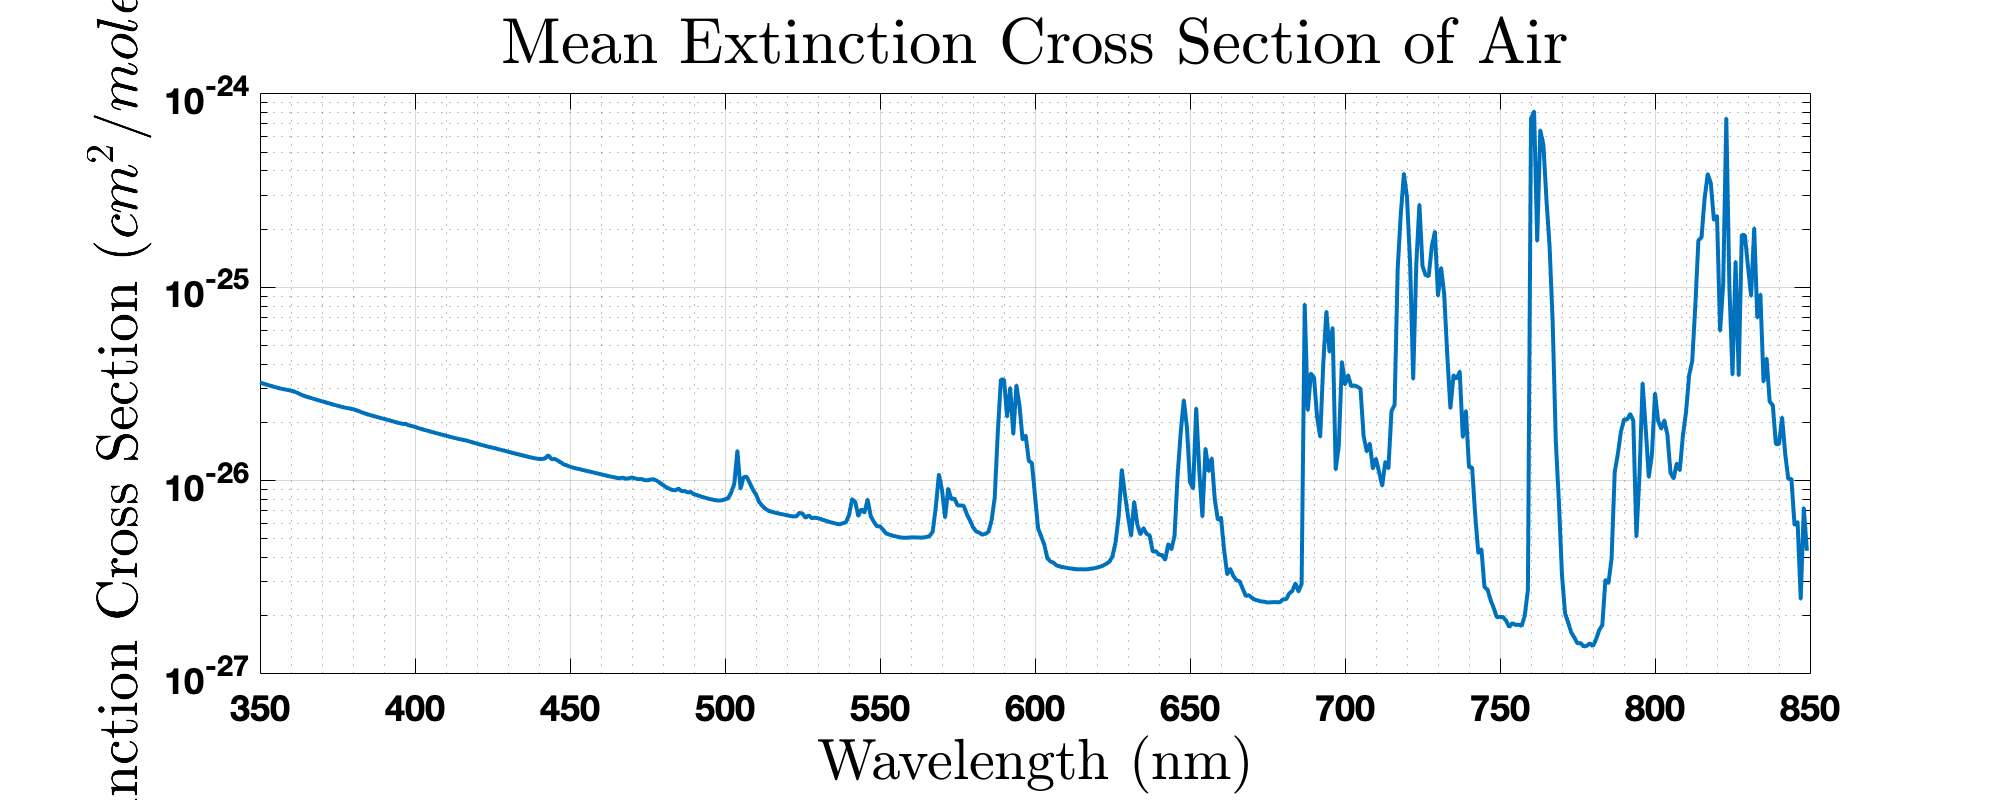


% First lets plot the mean molecular extinction coefficient
f = figure; semilogy(wl,sigma_e,'LineWidth',2); 
grid on; grid minor
xlabel('Wavelength (nm)','interpreter','latex')
ylabel('Extinction Cross Section $$(cm^{2}/molecule)$$', 'interpreter','latex')
title('Mean Extinction Cross Section of Air','interpreter','latex')
set(f, 'Position', [0 0 1000 400])

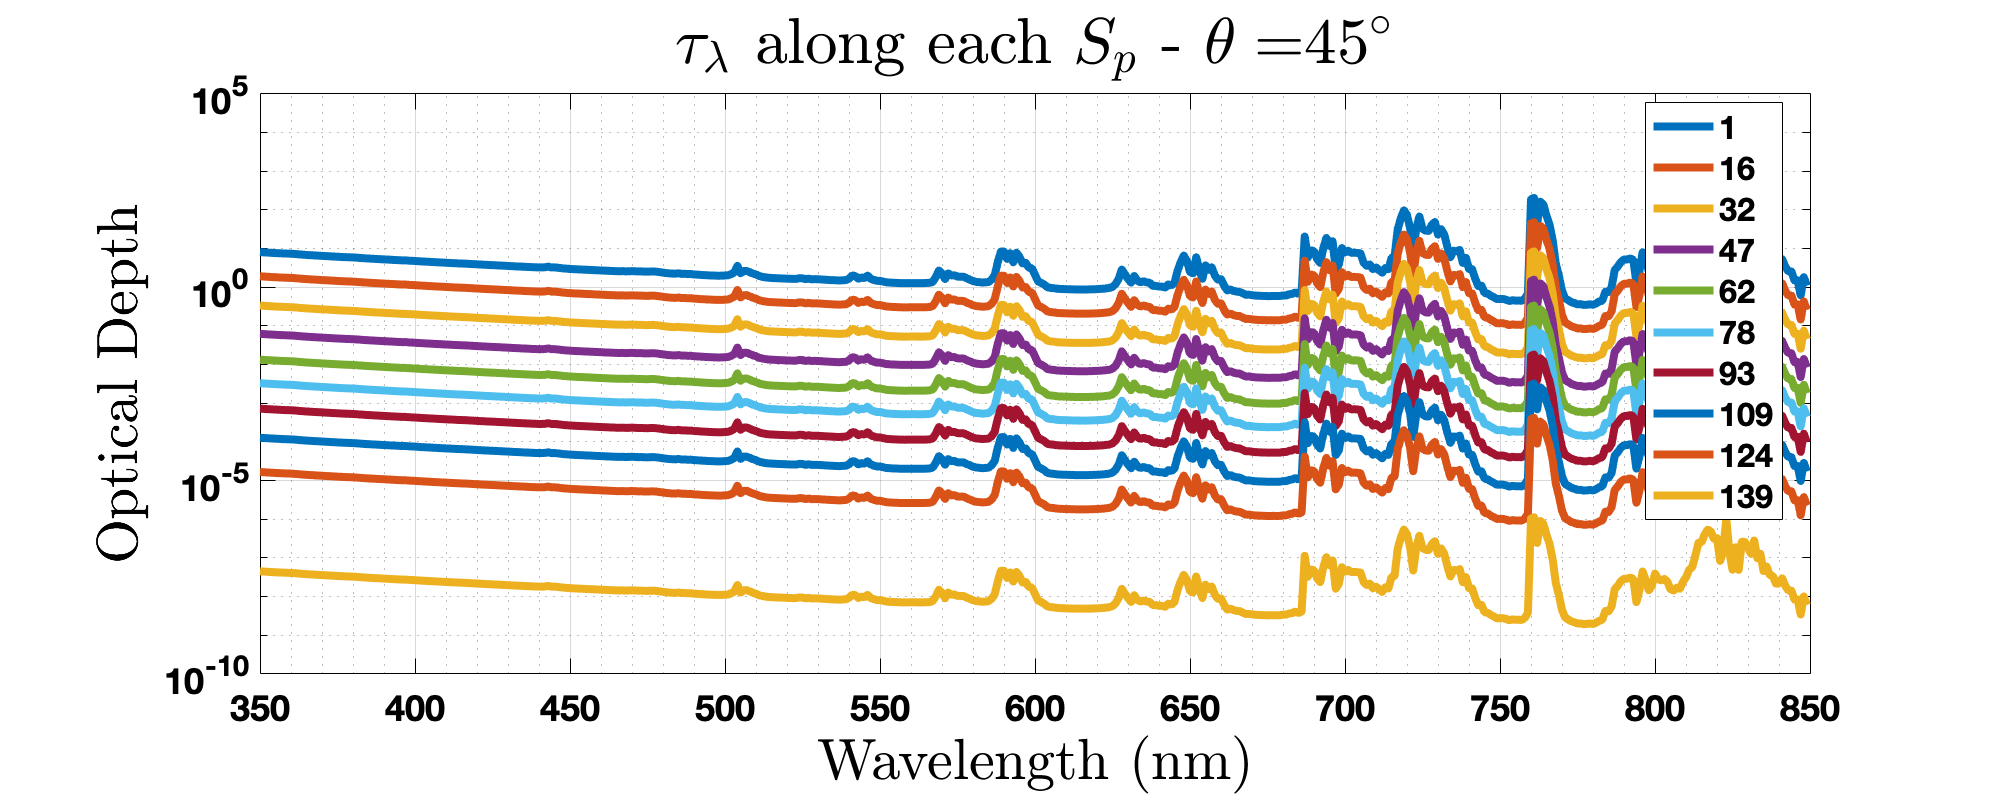


% --- Lets plot the optical depths across wavelength for each location
% along our line of sight
T_num = 1;
f = figure; semilogy(wl,tau(:,:,T_num)); grid on; grid minor
xlabel('Wavelength (nm)','interpreter','latex')
ylabel('Optical Depth', 'interpreter','latex')
title(['$$\tau_\lambda$$ along each $$S_p$$ - $$\theta = $$',num2str(theta(T_num)),'$$ ^{\circ} $$'],'interpreter','latex')
legend(string(round(L_p(T_num,:))),'location','best' )
set(f, 'Position', [0 0 1000 400])

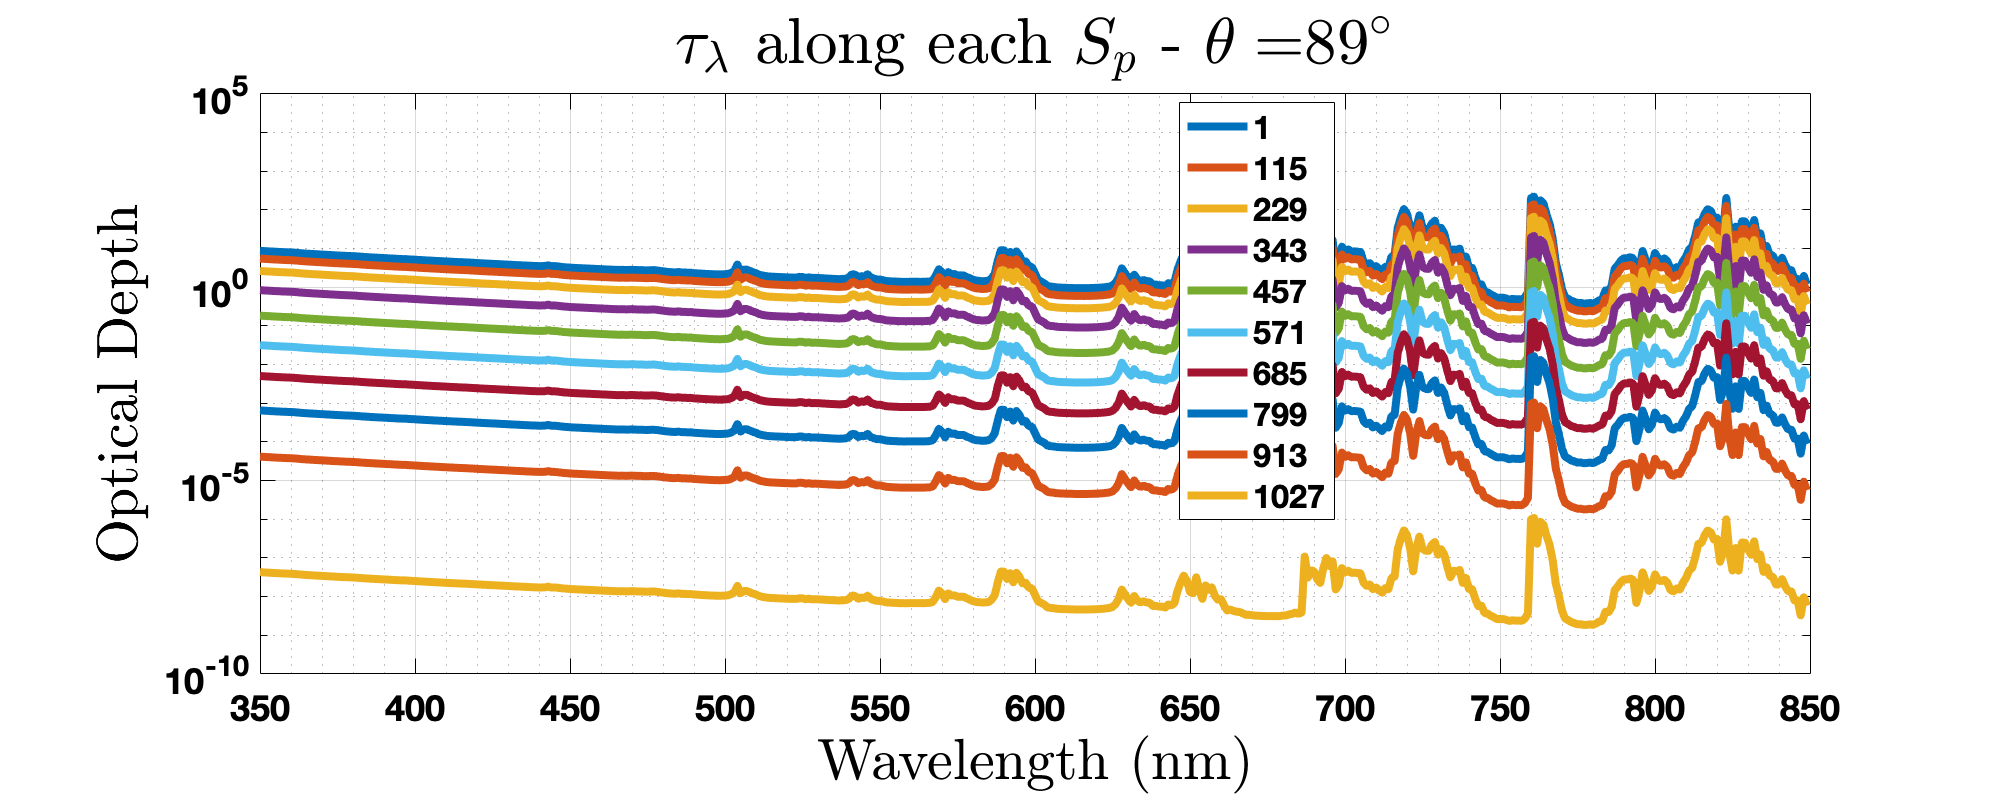


T_num = N_T;
f = figure; semilogy(wl,tau(:,:,T_num)); grid on; grid minor
xlabel('Wavelength (nm)','interpreter','latex')
ylabel('Optical Depth', 'interpreter','latex')
title(['$$\tau_\lambda$$ along each $$S_p$$ - $$\theta = $$',num2str(theta(T_num)),'$$ ^{\circ} $$'],'interpreter','latex')
legend(string(round(L_p(T_num,:))),'location','best' )
set(f, 'Position', [0 0 1000 400])



% Or we can visualize the optical depth across wavelengths and at each
% point along our line of sight

% for tt = 1:N_T
%     f = figure; imagesc(L_p(tt,:), wl,log10(tau(:,:,tt))); colorbar
%     ylabel('Wavelength (nm)','interpreter','latex')
%     xlabel('Depth along line of sight (km)', 'interpreter','latex')
%     title(['$$log_{10}(\tau_\lambda)$$ along each $$S_p$$ - $$\theta = $$',num2str(theta(tt)),'$$ ^{\circ} $$'],'interpreter','latex')
%     set(f, 'Position', [0 0 800 400])
% end

## Compute the Radiance scattered along our line of sight L

#### The differential solid angle is defined as $d\Omega = \sin(\theta) \, d\theta \, d\phi$

% I have to integrate over a solid angle. But I'm intersted in light being
% scattering along a particular direction, not a range. Lets recall that
% the human eye does have a significant field of view. Lets estimate this
theta_humanEye = [45, 135];             % range of the zenith angle for the human eye
phi_humanEye = [-60, 60];               % range of the azimuthal angle for the human eye

% --- Lets make the solid angle much smaller ---
% Imagine looking down our line of sight. We define a small field of view
% that perceives this part of the sky

N_theta = 10;
N_phi = 10;

dTheta = linspace(theta_humanEye(1), theta_humanEye(2),N_theta);    % vector spanning the solid angle
dPhi = linspace(phi_humanEye(1), phi_humanEye(2),N_phi);    % vector spanning the solid angle

% I need to introduce the phase function!
% For now lets assume its equally likely to scatter in any direction

P = 0.01.*ones(N_W,N_L,N_theta, N_phi);

% We need the single scattering albedo
% I'm fuding this for now

ssa = 0.5;


% --- Read in the Solar Spectrum ---
% This is the solar flux at the top of the atmosphere
solar_flux = read_solar_flux_file([wl(1), wl(end)], 'kurudz_1.0nm.dat');            % W/m^2/nm
solar_radiance = solar_flux*(con.au/con.R_sun)^2 /pi;                               % W/m^2/nm/sr

% The first integral estimates the total contribution of scattering over
% the solid angle of the human eye

F_wl = zeros(N_W, N_T);
F_total = zeros(1,N_T);

for tt = 1:N_T
    
    Int_overZenith = trapz(dTheta,sind(theta(tt)) .* repmat(solar_radiance,1,N_L,N_phi,N_theta)...
        .*repmat(T(:,:,tt),1,1,N_phi,N_theta) .*P .*repmat(sigma_e,1,N_L,N_phi,N_theta) ...
        .*repmat(Nc_z(tt,:,1),N_W,1,N_phi,N_theta),4);


    % Now we integrate over the azimuth angle
    Int_overAzimuth = trapz(dPhi, 1/(4*pi) .* Int_overZenith,3);

    % Now we integrate along the path length
    % This gives us the spectral flux along our line of sight at theta for
    % each wavelength of interest
    F_wl(:,tt) = trapz(L_p(tt,:), ssa.*Int_overAzimuth,2);                              % W/m^2/nm

    % we can integrate over wavelength to get the total power per unit area at the observer
    F_total(tt) = trapz(wl, F_wl(:,tt));                                          % W/m^2

end


## Lets plot the spectrum over different Theta values

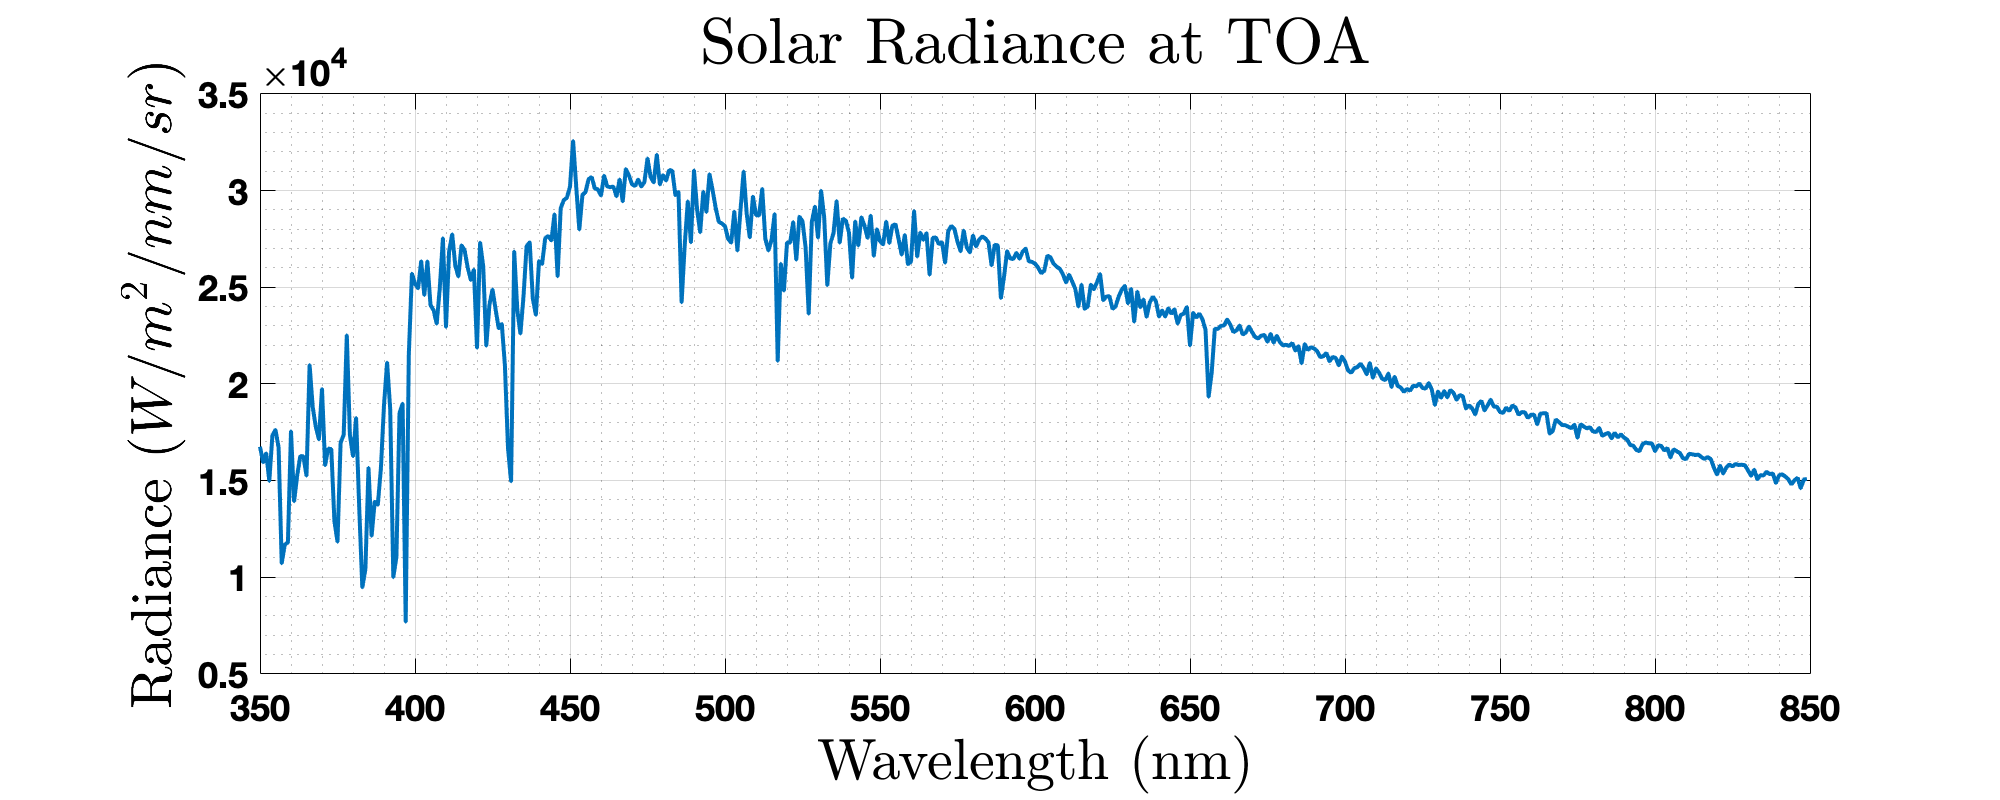

% Lets plot the Solar Spectral Radiance
f = figure; plot(wl, solar_radiance, 'LineWidth',2)
grid on; grid minor
xlabel('Wavelength (nm)','interpreter','latex')
ylabel('Radiance $$ (W/m^{2}/nm/sr) $$', 'interpreter','latex')
title('Solar Radiance at TOA','interpreter','latex')
set(f, 'Position', [0 0 1000 400])

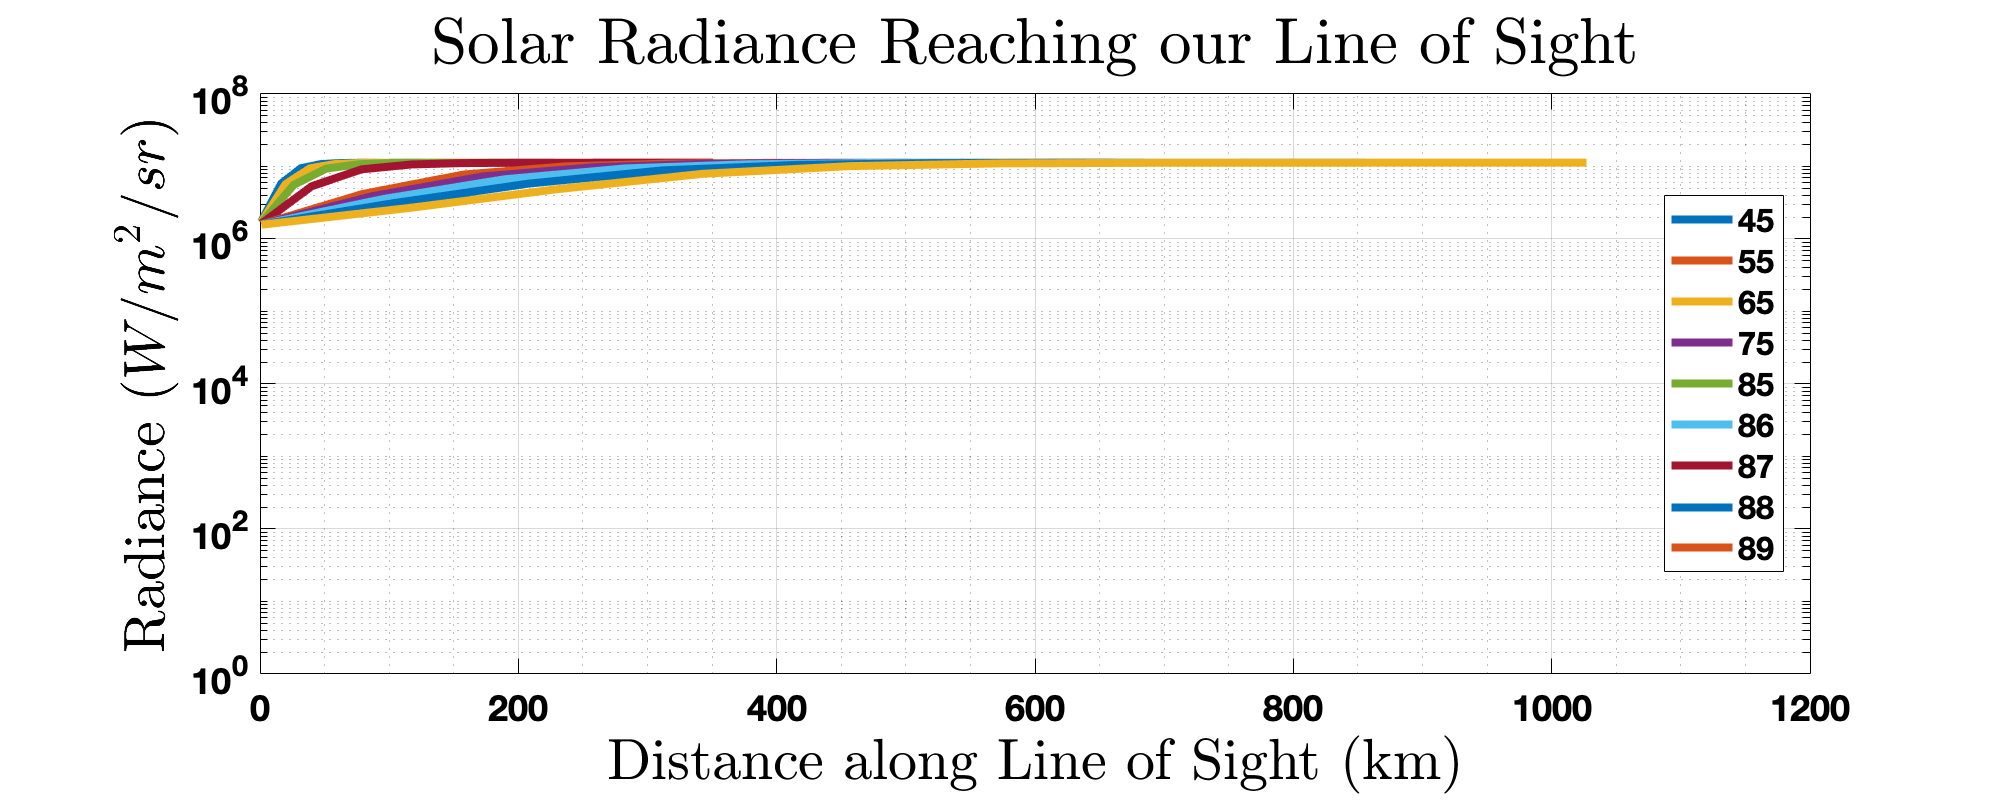


% First lets plot the amount of solar radiance transmitted through the
% atmosphere along our line of sight

f = figure; 
for tt = 1:N_T
   semilogy(L_p(tt,:),trapz(wl,T(:,:,tt).*repmat(solar_radiance,1,N_L),1),N_T,N_L)
   hold on
end
%ylim([1e-2,1e6])
grid on; grid minor
xlabel('Distance along Line of Sight (km)','interpreter','latex')
ylabel('Radiance $$ (W/m^{2}/sr) $$', 'interpreter','latex')
title('Solar Radiance Reaching our Line of Sight','interpreter','latex')
legend(string(theta),'location','best' )
set(f, 'Position', [0 0 1000 400])

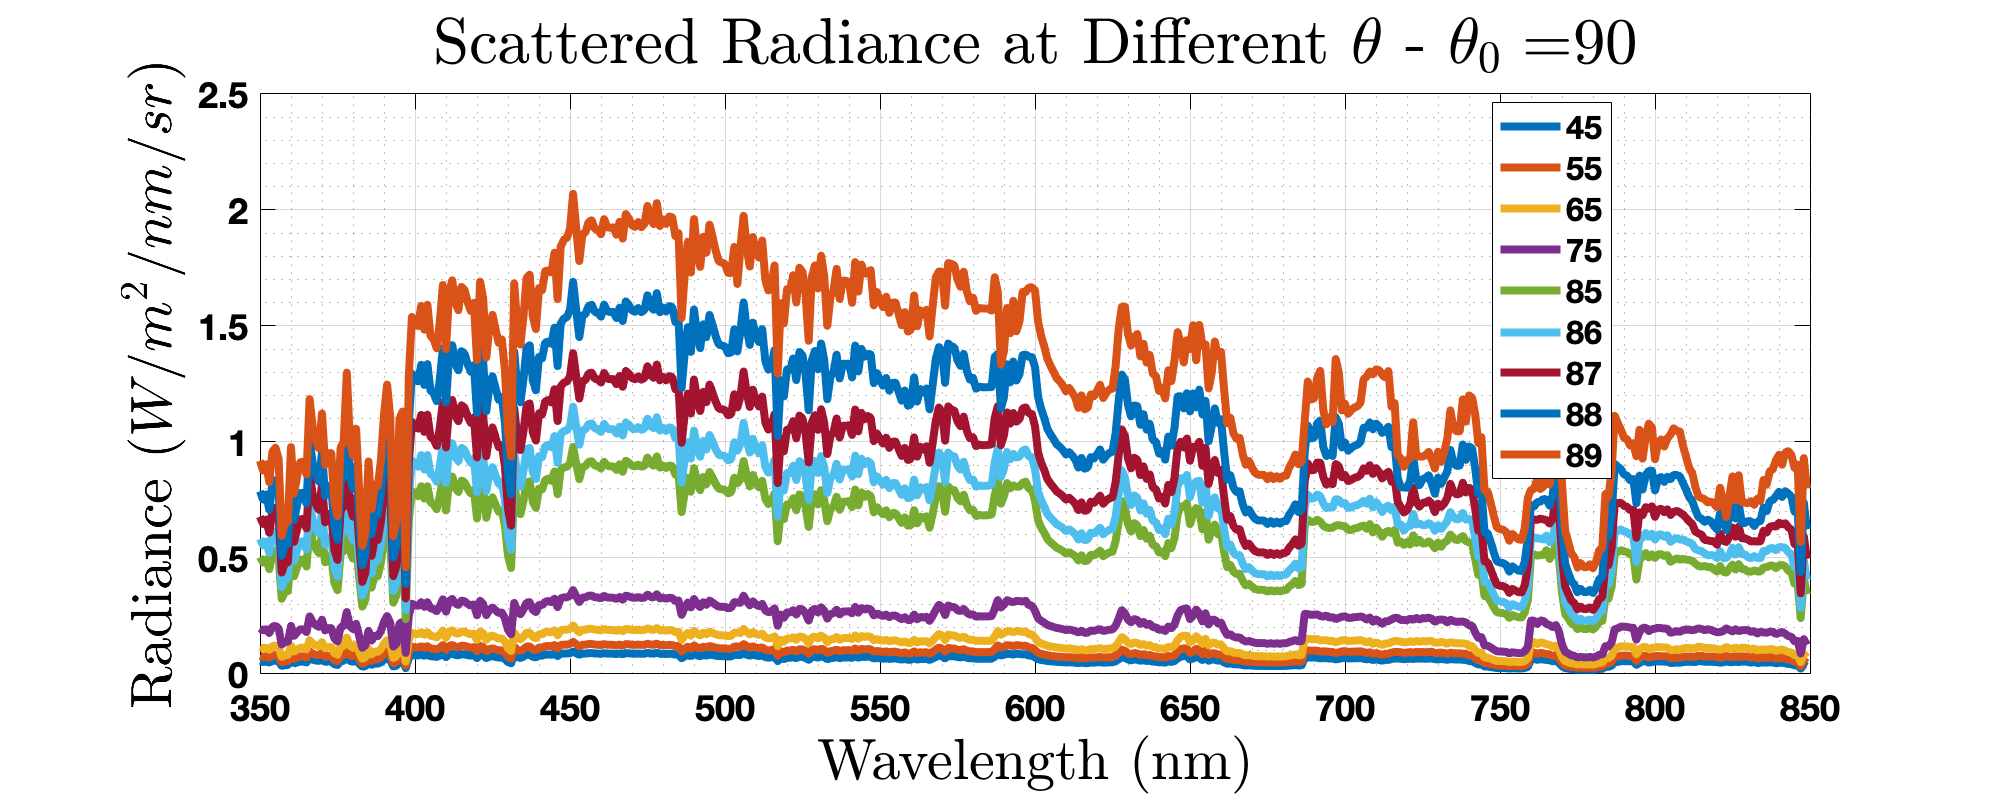



% Next lets plot the integrated spectral radiance at our observer along each line of sigh 
f = figure; plot(wl,F_wl)
grid on; grid minor
xlabel('Wavelength (nm)','interpreter','latex')
ylabel('Radiance $$ (W/m^{2}/nm/sr) $$', 'interpreter','latex')
title(['Scattered Radiance at Different $$\theta$$ - $$\theta_0 = $$',num2str(theta0)],'interpreter','latex')
legend(string(theta),'location','best' )
set(f, 'Position', [0 0 1000 400])

## Convert Spectra into RGB Colors

% We assume our model is azimuthally symmetric
% Lets compute the RGB color using the above spectra at each zenith angle

RGB0 = uint8(zeros(3, N_T));

% ----- Introduce the CIE Color Matching Functions -----

% x is the red (long) cell response
% y is the green (medium) cell response
% z is the blue (short) cell response

[lambda, x_func, y_func, z_func] = colorMatchFcn('CIE_1931');

% Lets interpolate the XYZ color functions so the have the same resolution
% as our transmission spectrum
index = wl>=min(lambda) & wl<=max(lambda);

x_funcT = interp1(lambda,x_func,wl(index));
y_funcT = interp1(lambda,y_func,wl(index));
z_funcT = interp1(lambda,z_func,wl(index));

% Step through each zenith angle


pos = [2 4 2 2];
for tt = 1:N_T
    
    % Lets determine the CIE-XYZ color values
    X = trapz(wl(index), x_funcT.*F_wl(index,tt));
    Y = trapz(wl(index), y_funcT.*F_wl(index,tt));
    Z = trapz(wl(index), z_funcT.*F_wl(index,tt));


    % We know normalize these values
    xyz = [X/(X+Y+Z), Y/(X+Y+Z), Z/(X+Y+Z)];

    % now we convert CIE XYZ values to sRBG values
    %-- Try different color spaces---
    %       'srgb'
    %       'adobe-rgb-1998'

    %-- Try different reference white points ---
    %       'd50' - color temp of 5003 K
    %       'd55' - color temp of 5500 K
    %       'd65' - color temp of 6504 K
    
    
    % -------------------------------------------------------
    % ---- Calculate RGB Using MATLAB Internal function -----
    %RGB = xyz2rgb(xyz, 'OutputType','uint16', 'ColorSpace', 'adobe-rgb-1998', 'WhitePoint',whitePoint);
    
    % -------------------------------------------------------
    % ----- Calculate RGB Using Inverted Color Matrix -------
    % How do I alter the reference white point?
    color_mat = [0.41847, -0.15866, -0.082835;...
                 -0.091169, 0.25243, 0.015708;...
                 0.00092090, -0.0025498, 0.17860];
    RGB = color_mat*xyz';
    % Convert to 8-bit image
    RGB0(:,tt) = uint8(255*(RGB./max(RGB)));
    
%     figure;
%     rectangle('Position',pos,'Curvature',[1 1], 'FaceColor',RGB0(:,tt), 'EdgeColor',[0,0,0])
%     set(gca,'XColor','k')
%     set(gca,'YColor','k')
%     axis equal
%     xlabel([num2str(theta(tt)), '$$ ^{\circ} $$'], 'interpreter','latex');

    
end


## Create a Plot of the Diffuse Sky

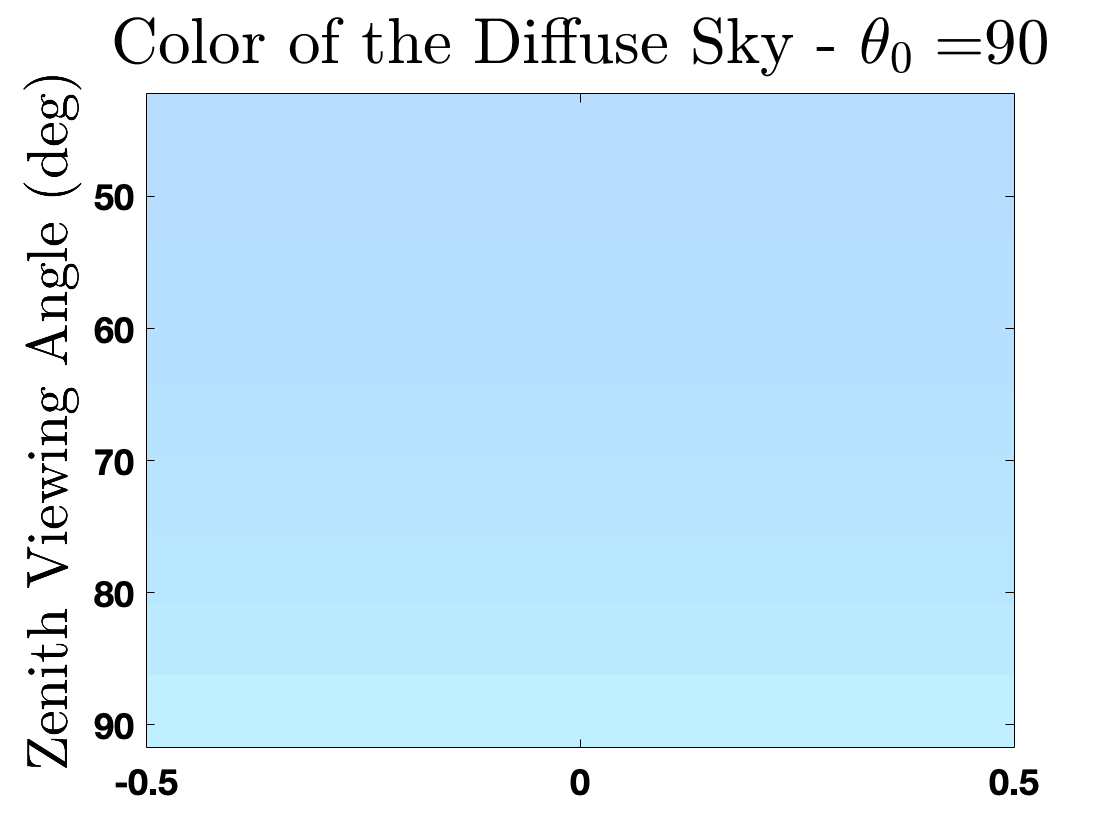



figure; image(0, theta',reshape(RGB0',N_T,1,3));
title(['Color of the Diffuse Sky - $$\theta_0 = $$',num2str(theta0)], 'interpreter','latex');
ylabel('Zenith Viewing Angle (deg)', 'interpreter','latex');

## Lets interpolate to get a smoother image

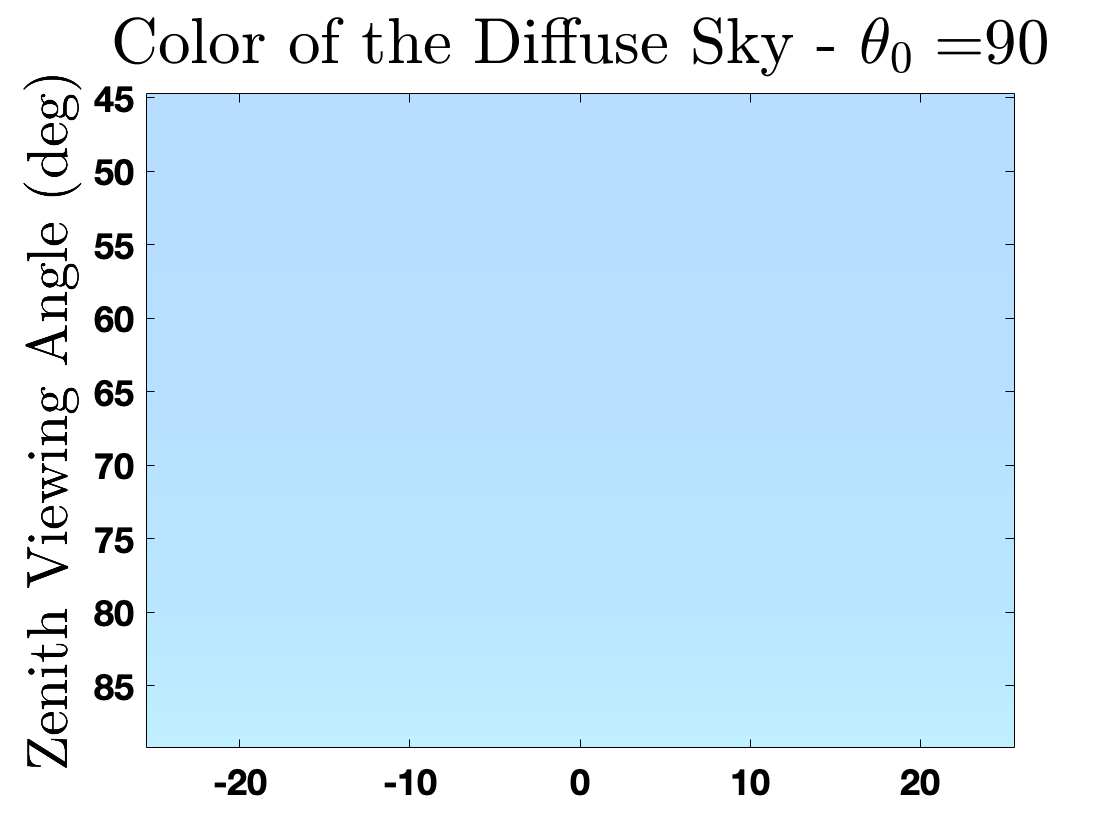


px_cols = 50;
px_rows = 100;

% Using gridded interpolation

sz = size(repmat(reshape(RGB0',N_T,1,3),1,px_cols,1));
xg = 1:sz(1);
yg = 1:sz(2);
interpGrid = griddedInterpolant({xg,yg},double(repmat(reshape(RGB0',N_T,1,3),1,px_cols,1)));

xq = (0:1/10:sz(1))';
yq = (0:1:sz(2))';
RGB_large = uint8(interpGrid({xq,yq}));

figure; image(-px_cols/2:(px_cols/2), linspace(min(theta),max(theta),size(RGB_large,1)),RGB_large);
title(['Color of the Diffuse Sky - $$\theta_0 = $$',num2str(theta0)], 'interpreter','latex');
ylabel('Zenith Viewing Angle (deg)', 'interpreter','latex');